clear all
% data = readtable('C:\Users\thoma\Downloads\BOOK1.xlsx') 
data=readtable("C:\Users\thoma\Documents\Eurostoxx.xlsx",'Sheet','Sheet2','Range','A1:G1608')

data = 1607×7 table
       Date        Open      High      Low      Close       Volume      SMAVG_15_ 
    __________    ______    ______    ______    ______    __________    __________

    05/04/2019    3445.1    3446.1    3440.3    3441.3             0           NaN
    04/04/2019    3434.3    3449.4    3425.2    3441.9    3.7192e+08    4.7233e+08
    03/04/2019    3399.9    3435.9    3399.9    3435.6    4.1543e+08    4.7874e+08
    02/04/2019    3386.2    3402.8    3382.8    3395.7     3.797e+08    4.7408e+08
    01/04/2019    3353.7      3391    3353.7    3385.4     6.986e+08    4.7086e+08
    29/03/2019    3326.4    3354.3    3326.4    3351.7    4.0559e+08    4.4616e+08
    28/03/2019    3321.3    3337.6    3315.9    3320.3     3.423e+08    4.506


%Vender data om.
data = flipud(data); 
data.Date = datetime(data.Date,'ConvertFrom','excel'); 
logreturn= [nan; 100*diff(log(data.Close))]

logreturn =        NaN
    2.8174
   -0.3706
    0.3005
   -0.5103
   -0.1526
    0.5536
    0.0694
    0.3509
   -0.0968


% Startværdier og begrænsninger for koefficienterne. 
%Første er konstant i varians. Næste er alpha, beta og den sidste er
%risikopræmien
startvaerdier = [1,0.1, 0.095, 0.90, 0.1]

startvaerdier =     1.0000    0.1000    0.0950    0.9000    0.1000


nanmean(logreturn)

ans = 0.0166

LB = [0 -0.02 0 0 0];
UB = [2 1 1 2 inf]; 
A = [0 1 0.5 1 0]; 
b = 1;
T = size(logreturn,1);

%backcast funktion til at sætte gang i algoritmen.
w = 0.05*.9.^(0:T-2); 
backCast= w*logreturn(2:end).^2;
%Indstillinger for fmincon.
options = optimset('fmincon'); 
options.Display = 'iter'; 
options.Algorithm = 'sqp'; 
options.Functiontolerance=1/100000000000;
options.TolCon=1/100000000000;

%Det er her jeg kalder funktionen defineret i bunden:
%fejlled=logreturn-r/252+h/2-lambda*sqrt(h). Fejlled=epsilon,
%logreturn=y=det simulerede afkast, h=den betingede varians

% Samme definition som ovenover
%     h(i) = omega+alpha*(fejlled(i-1)).^2+gamma*(fejlled(i-1)).^2*(fejlled(i-1)<0)+beta*h(i-1); 
[estimates,fval,output,exitflag,lambda,gradient,hessian] = fmincon(@GJRGARCHlikelihood, startvaerdier, A, b, [], [], LB, UB, [], options, logreturn(2:end), backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    3.527117e+03     4.750e-02     1.000e+00     0.000e+00     7.234e+03  
Objective function returned complex; trying a new point...
    1          13    2.834256e+03     0.000e+00     7.000e-01     3.256e+00     6.772e+03  
    2          21    2.597656e+03     0.000e+00     4.900e-01     2.130e+01     4.894e+03  
    3          28    2.456550e+03     0.000e+00     7.000e-01     1.716e+01     2.447e+03  
    4          34    2.452196e+03     1.735e-17     1.000e+00     7.480e+00     2.205e+02  
Objective function returned complex; trying a new point...
    5          48    2.451762e+03     1.735e-17     5.765e-02     5.627e+00     2.604e+02  
    6          54    2.402956e+03     0.000e+00     1.000e+00     3.144e+00     1.280e+02  
    7          60    2.375248e+03     2.220e-16     1.00

hessian

hessian = 	1.0e+05 *

    1.7295    1.0038    0.4112    1.2674    0.0006
    1.0038    0.9013    0.3375    0.9498    0.0005
    0.4112    0.3375    0.1743    0.3934    0.0003
    1.2674    0.9498    0.3934    1.1424    0.0003
    0.0006    0.0005    0.0003    0.0003    0.0000


fval

fval = 2.2528e+03

output

output = 2

exitflag

exitflag = struct with fields:
         iterations: 38
          funcCount: 277
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-11.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   2.80e-08                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-11 (selected)'
    constrviolation: 0
           stepsize: 5.5846e-08
       lssteplength: 1
      firstorderopt: 3

lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


%Tjek førsteordensbetingelser.
gradient

gradient = 	1.0e+-3 *

   -0.3052
   -0.0610
   -0.3967
    0.0305
   -0.0074


eig(hessian)

ans = 	1.0e+05 *

    0.0000
    0.0284
    0.0515
    0.2659
    3.6017


%Tjek for maksimum
any(eig(hessian)==0)

ans = logical
   0


lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


estimates

estimates =     0.0273   -0.0125    0.1811    0.9025    4.1243


%Jeg henter fejlled og h ud for at kunne finde standardfejlene.
[ll,lls,h,fejlled]=GJRGARCHlikelihood(estimates, logreturn(2:end), backCast)

ll = 2.2528e+03

lls =     0.6332
    0.7362
    0.6904
    0.8376
    0.6243
    0.8823
    0.5610
    0.6674
    0.5243
    0.7895


h =     0.5647
    0.5369
    0.5351
    0.5091
    0.5308
    0.5103
    0.4840
    0.4641
    0.4446
    0.4301


fejlled =     0.0000
   -0.3711
    0.3000
   -0.5108
   -0.1531
    0.5531
    0.0690
    0.3504
   -0.0973
   -0.5015



% News curve og qq plot
 standardfejl=fejlled./sqrt(h)

standardfejl =     0.0000
   -0.5065
    0.4102
   -0.7158
   -0.2101
    0.7742
    0.0991
    0.5144
   -0.1459
   -0.7647


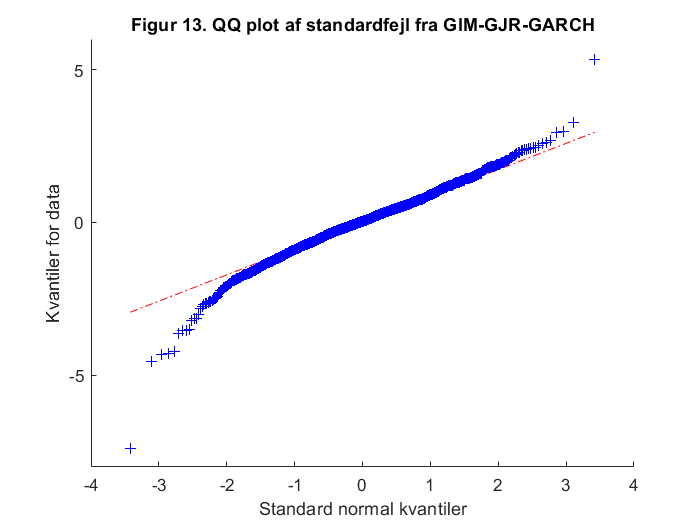

qqplot(standardfejl)
title('Figur 13. QQ plot af standardfejl fra GIM-GJR-GARCH')
xlabel('Standard normal kvantiler')
ylabel('Kvantiler for data')
yticks([-10,-5,0,5,10])


 omega=estimates(:,1)/10000

omega = 2.7291e-06

gamma=estimates(:,3)

gamma = 0.1811

alpha=estimates(:,2)

alpha = -0.0125

beta=estimates(:,4)

beta = 0.9025

lambda1=estimates(:,5)

lambda1 = 4.1243

gen= sqrt(nanvar(logreturn))/100

gen = 0.0109

tilfal=rand(1,10000)-1/2

tilfal =     0.1853    0.1340    0.1883   -0.0118    0.2854   -0.1292    0.4916   -0.2463   -0.1069    0.2666    0.2384   -0.1858    0.2772    0.3934   -0.1704   -0.2607   -0.3514   -0.4798    0.2388    0.1971    0.4432    0.3632    0.0136   -0.3086   -0.1420    0.1337   -0.4518   -0.1352    0.0927    0.3758   -0.3552   -0.4706   -0.4091    0.3224    0.0849    0.4945   -0.1486    0.0127    0.4254    0.0828   -0.2692   -0.2316    0.4926    0.0158    0.0040    0.4509   -0.2166    0.1200    0.3211   -0.4684


tilfal=sort(tilfal)

tilfal =    -0.4999   -0.4999   -0.4997   -0.4995   -0.4994   -0.4993   -0.4992   -0.4991   -0.4990   -0.4985   -0.4985   -0.4984   -0.4981   -0.4980   -0.4980   -0.4979   -0.4978   -0.4977   -0.4976   -0.4974   -0.4973   -0.4970   -0.4969   -0.4967   -0.4966   -0.4965   -0.4963   -0.4962   -0.4962   -0.4961   -0.4961   -0.4960   -0.4958   -0.4957   -0.4956   -0.4956   -0.4954   -0.4954   -0.4952   -0.4952   -0.4950   -0.4950   -0.4949   -0.4944   -0.4942   -0.4941   -0.4941   -0.4940   -0.4939   -0.4937


hi=zeros(1,10000)

hi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


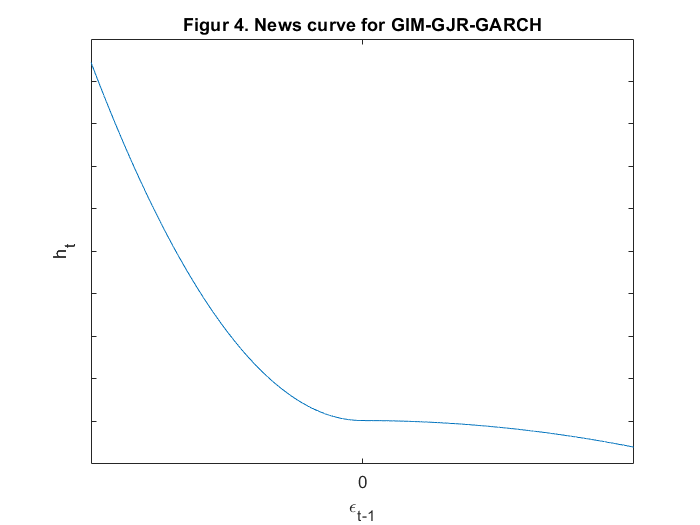

for i=1:10000;
hi(i)=omega+beta*gen^2+alpha*tilfal(i).^2+gamma*tilfal(i).^2*(tilfal(i)<0);
end

plot(tilfal,hi)
title('Figur 4. News curve for GIM-GJR-GARCH')
xlabel('\epsilon_t_-_1')
ylabel('h_t')
xticks([0])
xticklabels([0])
yticklabels([])

%Standardiseret fejl og test
[ll,lls,h,fejlled]=GJRGARCHlikelihood(estimates, logreturn(2:end), backCast)

ll = 2.2528e+03

lls =     0.6332
    0.7362
    0.6904
    0.8376
    0.6243
    0.8823
    0.5610
    0.6674
    0.5243
    0.7895


h =     0.5647
    0.5369
    0.5351
    0.5091
    0.5308
    0.5103
    0.4840
    0.4641
    0.4446
    0.4301


fejlled =     0.0000
   -0.3711
    0.3000
   -0.5108
   -0.1531
    0.5531
    0.0690
    0.3504
   -0.0973
   -0.5015


ll=-ll

ll = -2.2528e+03

bic=aicbic(ll,length(estimates),length(logreturn(2:end)))

bic = 4.5156e+03

ll=-ll

ll = 2.2528e+03

ll

ll = 2.2528e+03

standardfejl=fejlled./sqrt(h)

standardfejl =     0.0000
   -0.5065
    0.4102
   -0.7158
   -0.2101
    0.7742
    0.0991
    0.5144
   -0.1459
   -0.7647


%første moment
mean(standardfejl)

ans = 0.0021

%andet moment
mean(standardfejl.^2)

ans = 0.9966

%tredje moment
mean(standardfejl.^3)

ans = -0.5142

%fjerde moment
mean(standardfejl.^4)

ans = 6.2099

%AR test
[h,pValue,stat,cValue]=lbqtest(standardfejl,'lags',5)

h = logical
   0


pValue = 0.2078

stat = 7.1771

cValue = 11.0705

%ARCH test
[h,pValue,stat,cValue]=lbqtest(standardfejl.^2,'lags',4)

h = logical
   0


pValue = 0.7698

stat = 1.8149

cValue = 9.4877

%Test statistik. Normalitet
[h,p,jbstat,critval]=jbtest(standardfejl)

h = 1

p = 1.0000e-03

jbstat = 783.1888

critval = 5.9548


% [ll,lls,h]=GJRGARCHlikelihood(estimates, logreturn(2:end), backCast)


%%%Her regner jeg standardfejlene ud ved sandwhichformlen.
%approximation af differentialet for at beregne varians nedenunder finder jeg I i sandwhichformlen
%Først tager jeg en meget lille ændring til hvert af parametrene.
forskel = 0.00001*estimates; 
antal=length(estimates)

antal = 5

bidrag = zeros(T-1,antal); 
for i=1:antal
    j = forskel(i); 
    delta = zeros(1,antal); 
    delta(i) = j;
        %Jeg finder ændringen i loglikelihood, hvis jeg bruger en smule større og mindre estimater.
[~, logliksplus] = GJRGARCHlikelihood(estimates + delta, logreturn(2:end), backCast);
[~, logliksminus] = GJRGARCHlikelihood(estimates - delta, logreturn(2:end), backCast);
bidrag(:,i) = (logliksplus - logliksminus)./(2*j);
end
logliksplus

logliksplus =     0.6332
    0.7362
    0.6904
    0.8376
    0.6243
    0.8823
    0.5610
    0.6674
    0.5243
    0.7895


delta

delta = 	1.0e+-4 *

         0         0         0         0    0.4124


% I=gradient*gradient'/T
I = bidrag'*bidrag/T

I =   234.6637  168.9081   61.8857  189.3623    0.0000
  168.9081  216.6715   75.4177  198.9499    0.0000
   61.8857   75.4177   28.3679   71.9494    0.0000
  189.3623  198.9499   71.9494  201.7460    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000


mean(bidrag)

ans = 	1.0e+-6 *

   -0.8779    0.2711    0.0098   -0.5089    0.0033


%Så skal J findes
J = hessian_beggesider(@GJRGARCHlikelihood, estimates, logreturn(2:end), backCast);
J = J/T

J = 	1.0e+13 *

   -0.9411   -2.0537   -0.1418   -0.0285   -0.0062
   -2.0537   -4.4814   -0.3095   -0.0621   -0.0136
   -0.1418   -0.3095   -0.0214   -0.0043   -0.0009
   -0.0285   -0.0621   -0.0043   -0.0009   -0.0002
   -0.0062   -0.0136   -0.0009   -0.0002   -0.0000


%Her inveterer jeg J.
Jinv = J\eye(length(J))

Jinv = 	1.0e+03 *

    0.0001   -0.0001    0.0003   -0.0002   -0.0017
   -0.0001    0.0001   -0.0003    0.0001   -0.0091
    0.0003   -0.0003    0.0026   -0.0010    0.0027
   -0.0002    0.0001   -0.0010    0.0005    0.0086
   -0.0017   -0.0091    0.0027    0.0086    3.1713


% Så kombineres J og I ved sandwhichformlen
vcv = Jinv*I*Jinv/T

vcv =     0.0008   -0.0005    0.0018   -0.0011    0.0097
   -0.0005    0.0003   -0.0014    0.0008   -0.0075
    0.0018   -0.0014    0.0086   -0.0040    0.0086
   -0.0011    0.0008   -0.0040    0.0022   -0.0110
    0.0097   -0.0075    0.0086   -0.0110    0.8609


%Nu tager jeg kvadratroden af diagonalen og får standardafvigelserne for estimateterne
se1=sqrt(diag(vcv))

se1 =     0.0276
    0.0182
    0.0930
    0.0467
    0.9279





%Her definerer jeg koefficienterne.
omega=estimates(:,1);
alpha=estimates(:,2);
gamma=estimates(:,3);
beta=estimates(:,4);
lambda1=estimates(:,5);
parametre=[omega alpha gamma beta lambda1]

parametre =     0.0273   -0.0125    0.1811    0.9025    4.1243


ttest=parametre'./se1

ttest =     0.9894
   -0.6871
    1.9478
   19.3402
    4.4449


standardafvigelse=se1'

standardafvigelse =     0.0276    0.0182    0.0930    0.0467    0.9279


ttest=parametre'./se1

ttest =     0.9894
   -0.6871
    1.9478
   19.3402
    4.4449



name={'omega';'alpha';'gamma';'beta';'lambda'}

name = 5×1 cell array
    {'omega' }
    {'alpha' }
    {'gamma' }
    {'beta'  }
    {'lambda'}


table(name, parametre',standardafvigelse',ttest)

ans = 5×4 table
      name        Var2         Var3       ttest  
    ________    _________    ________    ________

    'omega'      0.027291    0.027584     0.98936
    'alpha'     -0.012506    0.018202    -0.68709
    'gamma'       0.18111    0.092985      1.9478
    'beta'        0.90253    0.046666       19.34
    'lambda'       4.1243     0.92787      4.4449




% Jeg dividerer omega som er konstanten i variansen med 100 i anden
omega=estimates(:,1)/10000;
[ll,lls,h,fejlled]=GJRGARCHlikelihood(estimates, logreturn(2:end), backCast);
s=rng;
rng(2)
tilfaeldige=randn(169,100000);
sigma2=zeros(169,100000);
sigma2(1,:)=h(end)/10000

sigma2 = 	1.0e+-4 *

    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642    0.5642
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

y=zeros(169,100000);
S=zeros(169,100000);
r=zeros(169,100000);
r(1,:)=0;
y=zeros(169,100000);
S0=data.Close(end)

S0 = 3.4413e+03

S(1,:)=S0

S = 	1.0e+03 *

    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

 %Jeg simulerer y(t)=r-1/2*h(t)+epsilon(t). Som afkast under Q
 %Den betingede varians er givet ved
 %h(t)=omega+alpha*epsilon(t-1)^2+beta*h(t-1)
r=(1+0.00122043534)^(1/252)-1;
akkumuleretafkast=zeros(169,100000)

akkumuleretafkast =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     

for j= 1:100000
for i= 2:169
    %sigma2 er den betingede varians
    sigma2(i,j)= omega + alpha * (tilfaeldige(i-1,j)*sqrt(sigma2(i-1,j)))^2 + gamma * (tilfaeldige(i-1,j)*sqrt(sigma2(i-1,j)))^2 * (tilfaeldige(i-1,j)<0) + beta * sigma2(i-1,j);
    %y er det daglige afkast givet ved 
    y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)-sigma2(i,j)/2+r;
    %jeg samler de daglige afkast i r og tager tilsidst eksponential
    %funktionen til r i de enkelte periode.
    akkumuleretafkast(i,j)=y(i,j)+akkumuleretafkast(i-1,j);
    S(i,j)=exp(akkumuleretafkast(i,j))*S0;

    
end
end

faktiskepriser=readtable("C:\Users\thoma\Documents\Optioner.xlsx",'Sheet','Ark1','Range','A1:I157')

faktiskepriser = 156×9 table
    Strike           Ticker            Bid      Ask     Last      IVM      Volm     Arbejdsdage    Midtpunkt
    ______    ____________________    _____    _____    _____    ______    _____    ___________    _________

     3150     'SX5E 4/18/19 C3150'    285.3      298        0         0       47         9          291.65  
     3175     'SX5E 4/18/19 C3175'    268.3    273.2        0    22.032        0         9          270.75  
     3200     'SX5E 4/18/19 C3200'    243.4      248      246    20.106      288         9           245.7  
     3225     'SX5E 4/18/19 C3225'    218.7    223.2      218    18.884      101         9          220.95  
     3250 


% 
% % fakoption=faktiskepriser.Last.*(volume>100);
% % sum((fakoption>0))
fakoption=faktiskepriser.Midtpunkt

fakoption =   291.6499
  270.7499
  245.7000
  220.9500
  196.3500
  171.8000
  147.4500
  123.5000
  100.0500
   77.5000


Volume=faktiskepriser.Volm

Volume =           47
           0
         288
         101
        3619
        1430
        2306
          93
         708
         190


% Rigtigmaturity=(faktiskepriser.Arbejdsdage<49)
T=(faktiskepriser.Arbejdsdage)

T =      9
     9
     9
     9
     9
     9
     9
     9
     9
     9



likvidefakiotion=fakoption.*(Volume>100).*(T<50)

likvidefakiotion =          0
         0
  245.7000
  220.9500
  196.3500
  171.8000
  147.4500
         0
  100.0500
   77.5000


nanRows=any(isnan(likvidefakiotion),2)

nanRows = 156×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


zeroRows=any(likvidefakiotion==0,2)

zeroRows = 156×1 logical array
   1
   1
   0
   0
   0
   0
   0
   1
   0
   0


badRows=nanRows | zeroRows

badRows = 156×1 logical array
   1
   1
   0
   0
   0
   0
   0
   1
   0
   0


likvidefakiotion(badRows, :)=[]

likvidefakiotion =   245.7000
  220.9500
  196.3500
  171.8000
  147.4500
  100.0500
   77.5000
   56.5000
   37.7000
   22.7500


T(badRows, :)=[];
K=faktiskepriser.Strike;

% badRows=nanRows | zeroRows;
K(badRows, :)=[];

T=T'

T =      9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    49    49    49    49    49    49    49    49    49    49    49    49    49    49    49    49    49


K=K'

K =         3200        3225        3250        3275        3300        3350        3375        3400        3425        3450        3475        3500        3525        3550        3575        3600        3200        3250        3325        3350        3375        3400        3425        3450        3475        3500        3525        3550        3575        3600        3625        3650        3200        3300        3325        3350        3375        3400        3425        3450        3475        3500        3525        3550        3600        3625        3650        3675        3700


likvidefakiotion

likvidefakiotion =   245.7000
  220.9500
  196.3500
  171.8000
  147.4500
  100.0500
   77.5000
   56.5000
   37.7000
   22.7500


% % 
% 
r=(1+0.00122043534)^(1/252)-1

r = 4.8401e-06

R=(r+1)

R = 1.0000

antalT=length(T)

antalT = 49

option1maaned=zeros(1,antalT)

option1maaned =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:antalT
option1maaned(i)=mean(max(S(T(i),:)-K(i),0)).*exp(-(R.^T(i)-1));
end
option1maaned=option1maaned'

option1maaned =   241.4380
  216.5915
  191.8576
  167.3279
  143.1291
   96.7648
   75.4130
   56.0907
   39.3917
   25.8067


xlswrite('C:\Users\thoma\Documents\Bachelorprojekt\optionertillatex',option1maaned,'xlRange','F1:F63')
option1maaned=option1maaned'

option1maaned =   241.4380  216.5915  191.8576  167.3279  143.1291   96.7648   75.4130   56.0907   39.3917   25.8067   15.6037    8.6096    4.3055    1.9395    0.7904    0.2900  247.9591  201.9640  137.7606  118.1992   99.8413   82.8572   67.4414   53.7399   41.8247   31.7457   23.4384   16.7782   11.6272    7.7898    5.0348    3.1267  261.7869  178.6906  159.6865  141.5651  124.4097  108.3006   93.3421   79.5983   67.1070   55.8910   45.9447   37.2509   23.4281   18.1422   13.8084   10.3428    7.6145



for i=1:antalT
SE(i)=(option1maaned(i)-likvidefakiotion(i)).^2;
end

S0./K

ans =     1.0754    1.0671    1.0589    1.0508    1.0428    1.0272    1.0196    1.0121    1.0048    0.9975    0.9903    0.9832    0.9762    0.9694    0.9626    0.9559    1.0754    1.0589    1.0350    1.0272    1.0196    1.0121    1.0048    0.9975    0.9903    0.9832    0.9762    0.9694    0.9626    0.9559    0.9493    0.9428    1.0754    1.0428    1.0350    1.0272    1.0196    1.0121    1.0048    0.9975    0.9903    0.9832    0.9762    0.9694    0.9559    0.9493    0.9428    0.9364    0.9301


%Fordelt på moneyness
%Total
RMSEtot=sqrt(mean(SE))

RMSEtot = 24.9139



%Hvor der kun er tre slags moneyness
%Out of money
j=S0./K<=0.95

j = 1×49 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 7.6516

%At the money
j= 1.05>=S0./K & S0./K>0.95

j = 1×49 logical array
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 25.9939

%In the money
j=S0./K>1.05

j = 1×49 logical array
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 28.6320


%total
RMSEtot=sqrt(mean(SE))

RMSEtot = 24.9139

j=T==9

j = 1×49 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 3.1319

j=T==27

j = 1×49 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


%første måned
RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 23.3930

%anden måned
j=T==49

j = 1×49 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 35.5641

% %tredje måned
% j=T==69
% RMSEtot=sqrt(sum(SE.*j)./sum(j))
% %fjerde måned
% j=T==89
% RMSEtot=sqrt(sum(SE.*j)./sum(j))
% 
% %Sjette måned
% j=T==114
% RMSEtot=sqrt(sum(SE.*j)./sum(j))


%Implieds
r=(1+0.00122043534)^(1/252)-1;
x=-850:10:850

x =   -850  -840  -830  -820  -810  -800  -790  -780  -770  -760  -750  -740  -730  -720  -710  -700  -690  -680  -670  -660  -650  -640  -630  -620  -610  -600  -590  -580  -570  -560


K=S0+x

K =     2.5913    2.6013    2.6113    2.6213    2.6313    2.6413    2.6513    2.6613    2.6713    2.6813    2.6913    2.7013    2.7113    2.7213    2.7313    2.7413    2.7513    2.7613    2.7713    2.7813    2.7913    2.8013    2.8113    2.8213    2.8313    2.8413    2.8513    2.8613    2.8713    2.8813


tic
for j=1:100
for i=1:171
option(i,j)=mean(max(S(j+8,:)-K(i),0))*exp(-((1+r).^(8+j)-1));
end
end
toc

Elapsed time is 38.078431 seconds.


antaldage=1:100

antaldage =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


x=-850:10:850

x =   -850  -840  -830  -820  -810  -800  -790  -780  -770  -760  -750  -740  -730  -720  -710  -700  -690  -680  -670  -660  -650  -640  -630  -620  -610  -600  -590  -580  -570  -560


K=S0+x

K =     2.5913    2.6013    2.6113    2.6213    2.6313    2.6413    2.6513    2.6613    2.6713    2.6813    2.6913    2.7013    2.7113    2.7213    2.7313    2.7413    2.7513    2.7613    2.7713    2.7813    2.7913    2.8013    2.8113    2.8213    2.8313    2.8413    2.8513    2.8613    2.8713    2.8813


[Antaldage,K1]=meshgrid(antaldage,K)

Antaldage =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    1

K1 =     2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913
    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013
    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113
    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213  

Antaldage=Antaldage

Antaldage =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    1

option

option =   849.9119  850.0491  849.9879  849.9470  850.0605  849.9319  849.9004  849.9354  849.8475  849.9727  850.0311  849.9179  849.7935  849.8066  849.9055  850.0845  850.1800  850.0773  850.2660  850.0973  850.0789  850.2453  850.3439  850.3760  850.4244  850.5292  850.6993  850.9235  850.9528  851.0642
  839.9123  840.0496  839.9884  839.9476  840.0612  839.9326  839.9011  839.9362  839.8484  839.9738  840.0323  839.9192  839.7948  839.8083  839.9073  840.0870  840.1834  840.0813  840.2696  840.1018  840.0840  840.2508  840.3507  840.3832  840.4322  840.5379  840.7085  840.9334  840.9633  841.0755
  829.9128  830.0501  829.9889  829.9482  830.0618  829.9333  829.9018  829.9370  829.8493  829.9750  830.0335  829.9206  829.7962  829.8102  829.9092  830.0897  830.1871  830.0854  830.2734  830.1067  830.0895  830.2565  830.3577  830.3909  830.4406  830.5474  830.7182  830.9438  830.9744  831.0879
  819.9132  820.0506  819.9895  819.9487  820.0624  819.9339  819.9025  819.9378  819.85

r=0.00122043534

r = 0.0012

Volatility = blsimpv(S0,K1,r,Antaldage./252,option);
implieds=Volatility

implieds =        NaN    0.9438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.3093       NaN       NaN       NaN    0.2963    0.2973    0.3010    0.3118    0.3238    0.3341    0.3294    0.3296
       NaN    0.9328       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.3075       NaN       NaN       NaN    0.2949    0.2954    0.2988    0.3090    0.3205    0.3305    0.3259    0.3261
       NaN    0.9218       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.3055       NaN       NaN       NaN    0.2933    0.2935    0.2965    0.3062    0.3173    0.3270    0.3224    0.3226
       NaN    0.9109       NaN       NaN       NaN       NaN       NaN       NaN      

toc

Elapsed time is 38.378856 seconds.


K=S0./K

K =     1.3280    1.3229    1.3179    1.3128    1.3078    1.3029    1.2980    1.2931    1.2883    1.2834    1.2787    1.2739    1.2692    1.2646    1.2600    1.2554    1.2508    1.2463    1.2418    1.2373    1.2329    1.2285    1.2241    1.2198    1.2155    1.2112    1.2069    1.2027    1.1985    1.1944


%Volatility surface for moneyness
% K1=K1/S0
K12=S0./K1

K12 =     1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280    1.3280
    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229    1.3229
    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179    1.3179
    1.3128    1.3128    1.3128    1.3128    1.3128    1.3128    1.3128    1.3128    1.3128 

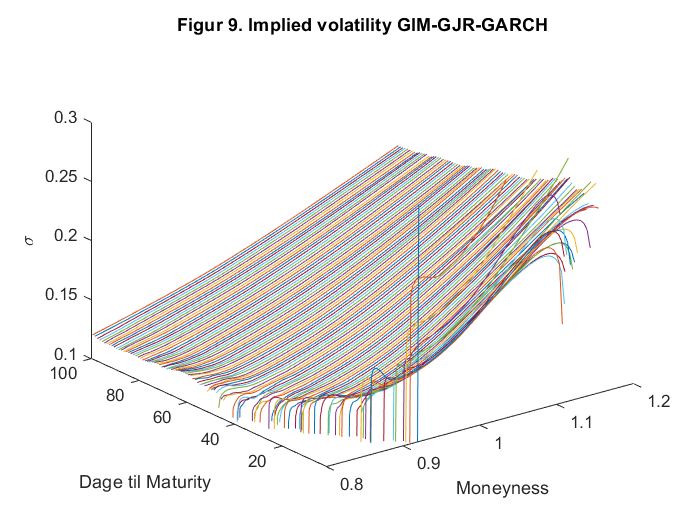

plot3(K12,Antaldage,implieds)
title('Figur 9. Implied volatility GIM-GJR-GARCH')
xlabel('Moneyness')
ylabel('Dage til Maturity')
zlabel('\sigma')
ylim([1 100])
xlim([0.8 1.2])
zlim([0.11 0.3])

xlim([0.800 1.200])
ylim([1.0 100.0])
zlim([0.100 0.300])
view([-37.500 30.000])

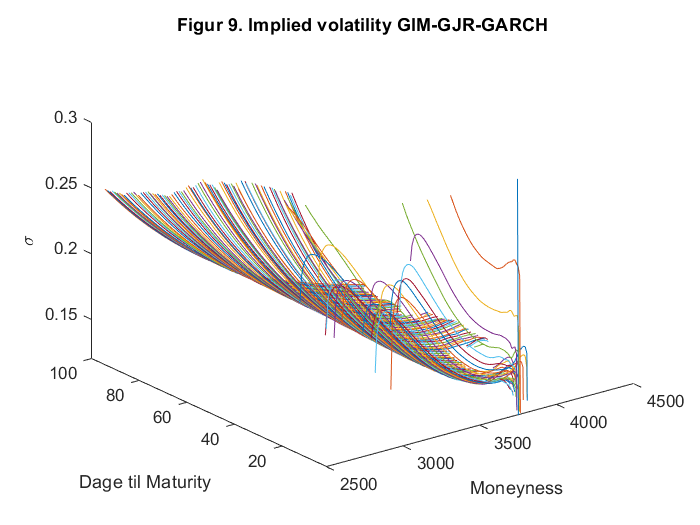

% 
plot3(K1,Antaldage,implieds)
title('Figur 9. Implied volatility GIM-GJR-GARCH')
xlabel('Moneyness')
ylabel('Dage til Maturity')
zlabel('\sigma')
ylim([1 100])
zlim([0.12 0.3])

function [ll,lls,h,fejlled] = GJRGARCHlikelihood(parameters, data, backCast)
omega = parameters(1);
alpha = parameters(2);
gamma = parameters(3);
beta = parameters(4);
lambda=parameters(5);
T = size(data,1);
h = zeros(T,1);
h(1) = backCast;
v=length(data)-length(parameters);
fejlled=zeros(T,1);
%Jeg issolerer for fejlled i ligningen for afkast under P
r=(1+0.00122043534)^(1/(252))-1;

fejlled=data-r*100+h/2-lambda*sqrt(h);
for i = 2:T 
    h(i) = omega+alpha*(fejlled(i-1)).^2+gamma*(fejlled(i-1)).^2*(fejlled(i-1)<0)+beta*h(i-1); 
end

lls = 0.5*(log(2*pi) + log(h) + fejlled.^2./h);

ll = sum(lls);
end
% Det her er funktion der finder J i sandwhichformlen der bliver brugt til at finde variansen:
%J er her givet ved: J(i,j)=(f(parametre+en lille ændring i to
%dimensioner)-f(parametre+lille ændring i en af
%parameter)-f(parametrene+lille ændring i den anden
%parametre)+f(parametrene))/(den lille ændring i hvet af parametrene ganget
%sammen).
function H= hessian_beggesider(funktion,parametre,varargin)
if size(parametre,2)>size(parametre,1)
    parametre=parametre';
end
%Jeg evaluere funktion med parametrene 
f=feval(funktion,parametre,varargin{:});
%En meget lille ændring af parametrene.
h=abs(parametre)*0.00001;
parametreh=h+parametre;
h=parametreh-parametre;
h=diag(h);

antal=size(parametre);

afledtep=zeros(antal);
afledten=zeros(antal);
%Jeg finder scoren lidt til over og under parametre væriderne.
for i=1:antal
    afledtep(i)=feval(funktion, parametre+h(:,i),varargin{:});
    afledten(i)=feval(funktion, parametre-h(:,i),varargin{:});
end
andenafledtep=zeros(antal);
andenafledten=zeros(antal);
%Nedenunder finder jeg de andenafledte ved at ændre to variable samtidigt.
for j=1:antal
    for i=j:antal
        andenafedtep(i,j)=funktion(parametre+h(:,j)+h(:,i),varargin{:});
        andenafledtep(j,i)=andenafledtep(i,j);
        andenafledten(i,j)=funktion(parametre-h(:,j)-h(:,i),varargin{:});
        andenafledten(j,i)=andenafledten(i,j);
    end
end
H=zeros(antal);
diagonal=diag(h);
GH=diagonal*diagonal';
%Tilsidst samles det hele sådan at J fås  
for i=1:antal
    for j=i:antal
        H(i,j)=(andenafledtep(i,j)+andenafledten(i,j)-afledtep(i)-afledten(i)-afledtep(j)-afledten(j)+f+f)/GH(i,j)/2;
        H(j,i)=H(i,j);
    end
end
end